# `Intro to Rotation Matricies`

# `Rotation and Transformation Matricies, 1/3`

`demonstrated`

`By Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`For tutoring purposes | Entry level Robotics | 11/23/2022`

`    A rotation matrix is an implicit representation of orientation. With three unit vectors defining new axis in the frame of another axis, rotation matricies avoid singularities of explicit representations. The way longitude and latitude change with repect to position near a pole is an example of a singularity. Rotation matricies can also be used to rotate a vector in space.`

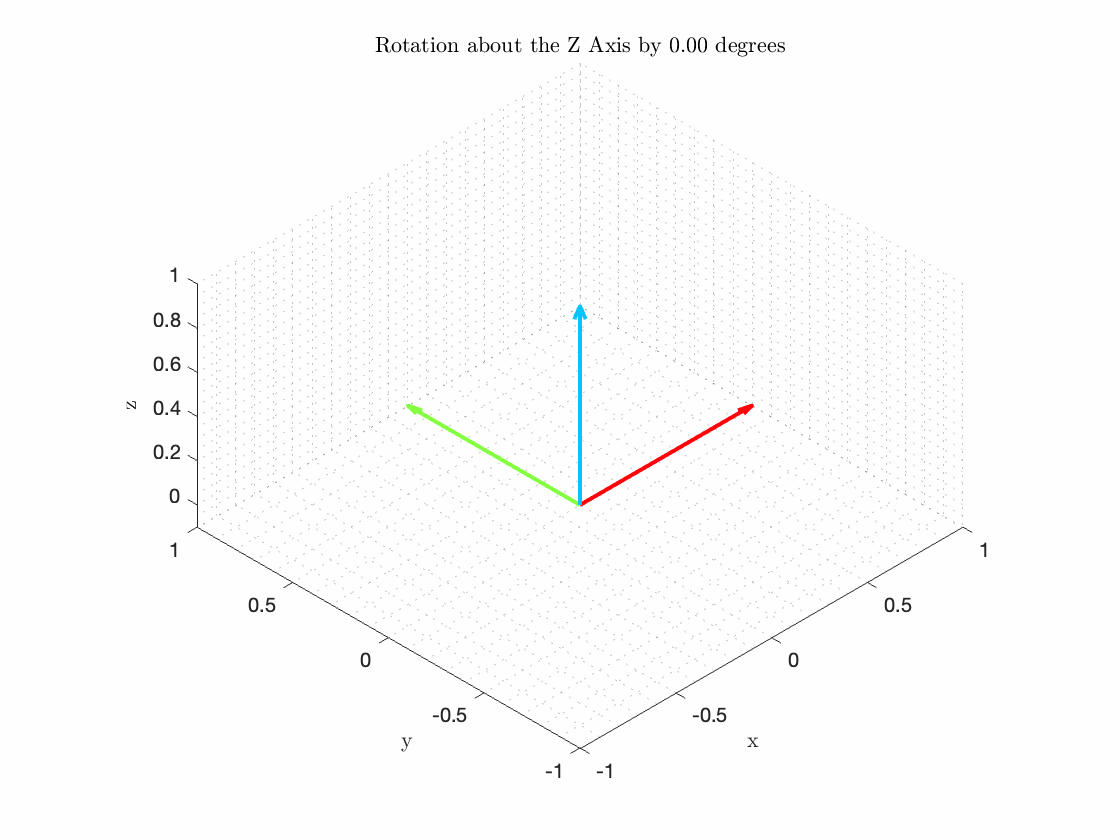

`The rotation matrix around an axis in terms of the angle can be represented:`

syms theta
rot_Z = rotZ(theta)

Functions for each axis. Note that rodrigues formula can be used to rotate about any axis

function rot = rotX(a)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Z axis
    rot = [1,0,0;0,cos(a),-sin(a);0,sin(a),cos(a)];
end

function rot = rotY(b)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Y axis
    rot = [cos(b),0,sin(b);0,1,0;-sin(b),0,cos(b)];
end

function rot = rotZ(g)
% useful for rigid-body motions
% takes an angle of rotation (radians)
% returns the corresponding rotation matrix, about the Z axis
    rot= [cos(g),-sin(g),0;sin(g),cos(g),0;0,0,1];
end